input = readmatrix('input.txt');
out = readmatrix('out.txt');
fs = 8000;
n_fft = 1024;

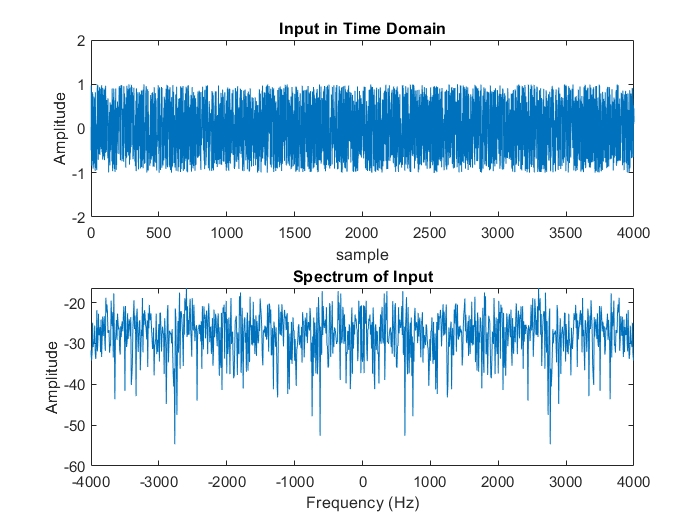

subplot(2,1,1);
plot(input)
ylim([-2 2])
title('Input in Time Domain')
xlabel('sample')
ylabel('Amplitude')
[s, freq] = spec(input, fs, n_fft);
subplot(2,1,2);
plot(freq, s)
title('Spectrum of Input')
xlabel('Frequency (Hz)')
ylabel('Amplitude')

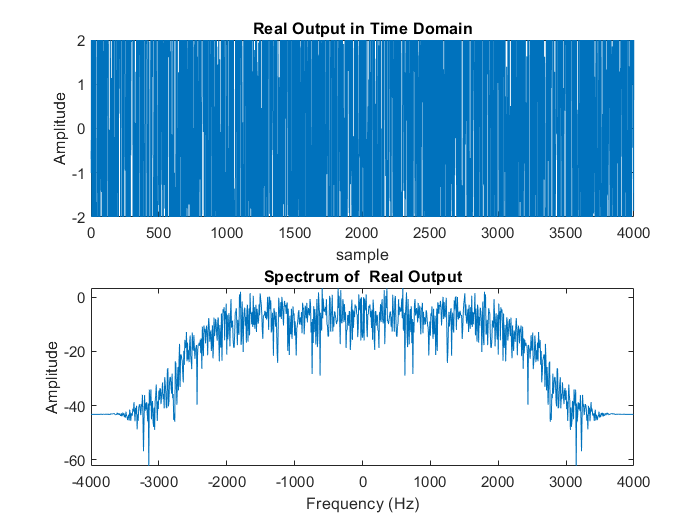

out_matab = sosfilt(SOS,input);
subplot(2,1,1);
plot(out_matab)
ylim([-2 2])
title('Real Output in Time Domain')
xlabel('sample')
ylabel('Amplitude')
[s, freq] = spec(out_matab, fs, n_fft);
subplot(2,1,2);
plot(freq, s)
title('Spectrum of  Real Output')
xlabel('Frequency (Hz)')
ylabel('Amplitude')

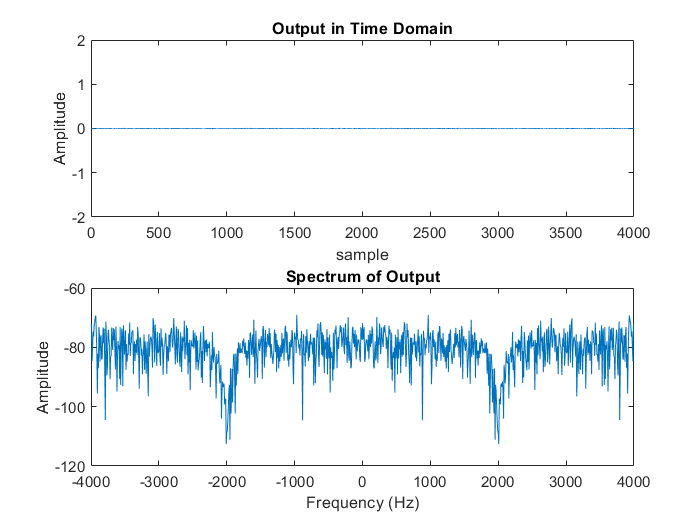

subplot(2,1,1);
plot(out)
ylim([-2 2])
title('Output in Time Domain')
xlabel('sample')
ylabel('Amplitude')
[s, freq] = spec(out, fs, n_fft);
subplot(2,1,2);
plot(freq, s)
title('Spectrum of Output')
xlabel('Frequency (Hz)')
ylabel('Amplitude')